% Subject list
sn={
    'S01';'S02';%'S03';'S04';'S05';'S06';'S07';'S08';'S09';'S10'
%     'S11';'S12';'S13';'S14';'S15';'S16';'S17';'S18';'S19';'S20'
%     'S21';'S22';'S23';'S24';'S25';'S26';'S27';'S28';'S29';'S30'
    };
% Trial list for subject 1
tn1={
    'EB_Ext_1';         'EB_Ext_2'
    'EB_Flex_1';        'EB_Flex_2'
    'EB_FlexExt_1';     'EB_FlexExt_1'
    'Extension_1';      'Extension_2'
    'Flexion_1';        'Flexion_2'
    'FlexionBox_1';     'FlexionBox_2'
    'LeftBox_1';        'LeftBox_2'
    'LeftFlexion_1';    'LeftFlexion_2'
    'RightBox_1';       'RightBox_2'
    'RightFlexion_1';   'RightFlexion_2'
    'RotationL_1';      'RotationL_2'
    'RotationR_1';      'RotationR_2'
    'SideL_1';          'SideL_1'
    'SideR_1';          'SideR_1'
    'UpnGo_1';          'UpnGo_2'
    };
% Trial list for subject 2
tn2={
    'EB_Box_L_1';       'EB_Box_L_2';       'EB_Box_L_3'
    'EB_Box_R_1';       'EB_Box_R_2';       'EB_Box_R_3'
    'EB_Ext_L_1';       'EB_Ext_L_2';       'EB_Ext_L_3'
    'EB_Ext_n_1';       'EB_Ext_n_2';       'EB_Ext_n_3'
    'EB_Ext_R_1';       'EB_Ext_R_2';       'EB_Ext_R_3'
    'EB_Flex_1';        'EB_Flex_2';        'EB_Flex_3'
    'EB_Flex_L_1';      'EB_Flex_L_2';      'EB_Flex_L_3'
    'EB_Flex_R_1';      'EB_Flex_R_2';      'EB_Flex_R_3'
    'EB_RotationL_1';	'EB_RotationL_2';	'EB_RotationL_3'
    'EB_RotationR_1';	'EB_RotationR_2';	'EB_RotationR_3'
    'EB_SideL_1';       'EB_SideL_2';       'EB_SideL_3'
    'EB_SideR_1';       'EB_SideR_2';       'EB_SideR_3'
    'ExBa_cont_1';      'ExBa_cont_2';      'ExBa_cont_3'
    'ExBa_Ext_1';       'ExBa_Ext_2';       'ExBa_Ext_3'
    'ExBa_Flex_1';      'ExBa_Flex_2';      'ExBa_Flex_3'
    'UpnGo_1';          'UpnGo_2';          'UpnGo_3'
    };
% Trial list for subjects 3 and on
tn3={
    'Box_L_1';      'Box_L_2';      'Box_L_3'
    'Box_R_1';      'Box_R_2';      'Box_R_3'
    'ExBa_cont_1';  'ExBa_cont_2';  'ExBa_cont_3'
    'ExBa_Ext_1';   'ExBa_Ext_2';   'ExBa_Ext_3'
    'ExBa_Flex_1';  'ExBa_Flex_2';  'ExBa_Flex_3'
    'Ext_L_1';      'Ext_L_2';      'Ext_L_3'
    'Ext_N_1';      'Ext_N_2';      'Ext_N_3'
    'Ext_R_1';      'Ext_R_2';      'Ext_R_3'
    'Flex_1';       'Flex_2';       'Flex_3'
    'Flex_L_1';     'Flex_L_2';     'Flex_L_3'
    'Flex_R_1';     'Flex_R_2';     'Flex_R_3'
    'Flex_box_1';   'Flex_box_2';   'Flex_box_3'
    'RotationL_1';  'RotationL_2';  'RotationL_3'
    'RotationR_1';  'RotationR_2';  'RotationR_3'
    'SideL_1';      'SideL_2';      'SideL_3'
    'SideR_1';      'SideR_2';      'SideR_3'
    'UpnGo_1';      'UpnGo_2';      'UpnGo_3'
    };

MissingFiles=cell(51,1);

im = 1

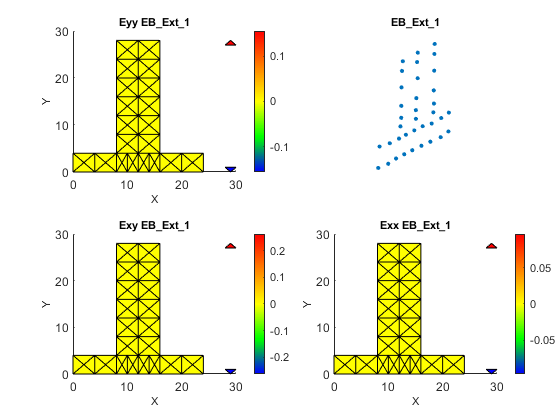

im = 1

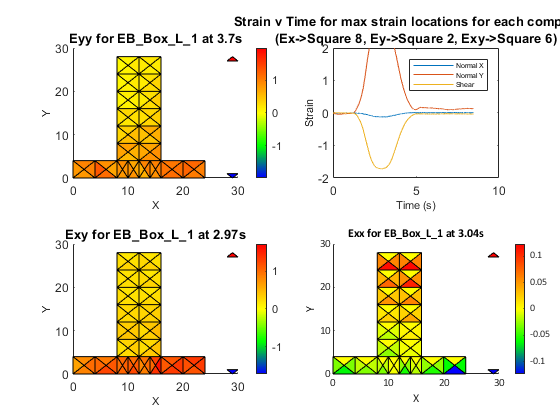


% MAKE SURE TO UPDATE THE PATHS TO REFLECT WHERE YOU HAVE THE
% STRAINANALYSIS FUNCTION AND SUBJECT DATA SAVED

% Specify folder where the StrainAnalysis.m function is saved
addpath('C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Matlab Code');

for j=1:length(sn) % Iterate through each subject
    % Reset missing file indexer
    im=1;
    % Specify folder where subjects' data is located (concatenate subject number to folder path)
    InputFolder=strcat('C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\',sn{j});
    addpath(InputFolder);
    % Specify the subjects' output folder.
    OutputFolder=strcat('C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\',sn{j});
    cd(OutputFolder);
    % Specify the trial list (it's different for subjects 1 and 2, then 3+ are all the same
    if j==1
        tn=tn1;
    elseif j==2
        tn=tn2;
    else
        tn=tn3;
    end
    % Run strain calculation function for each trial
    for i=1:length(tn)
        if isfile([InputFolder '\' tn{i} '.mat'])
            StrainAnalysis(tn{i},sn{j});
        else
            MissingFiles{im}=tn{i};
            im=im+1;
        end
    end
    if im>1
        save(strcat(sn,'_MissingFiles'),"MissingFiles")
    end
    % Remove the input folder before adding a new one at the reinitialization of the loop
    rmpath(['C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\' sn{j}]);
end